# COMP118 CW3: Mapping multi-contrast microstructural MRI of the placenta

## Task 1 - Load and plot the MRI volumes and masks

pip0101_image = im2double(niftiread("CW3\data\pip0101_20_20_1401_T2MEdiff_abs.alle.nii"));
pip0101_placenta_mask = niftiread("CW3\data\pip0101_placenta_mask.nii.gz");
pip0101_placenta_and_uterine_mask = niftiread("CW3\data\pip0101_placenta_and_uterine_wall_mask.nii.gz");

pip0120_image = im2double(niftiread("CW3\data\pip0120_20_20_2501_T2MEdiff_abs.alle.nii"));
pip0120_placenta_mask = niftiread("CW3\data\pip0120_placenta_mask.nii.gz");
pip0120_placenta_and_uterine_mask = niftiread("CW3\data\pip0120_placenta_and_uterine_wall_mask.nii.gz");

B1 = bwboundaries(pip0101_placenta_mask(:,:,7));
B2 = bwboundaries(pip0120_placenta_mask(:,:,7));

pip0101_size = size(pip0101_image)

pip0101_size =    200   106    30   330


pip0120_size = size(pip0120_image)

pip0120_size =    200   102    20   330


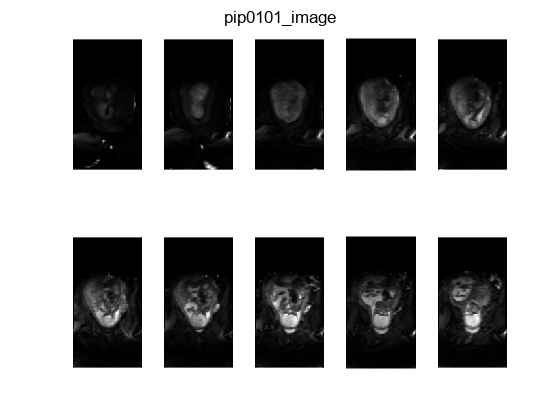

figure
sgtitle('pip0101\_image')
j= 1;
for i = 1:3:30
    subplot(2,5,j);
    img = pip0101_image(:,:,i,1);
    imshow(img,[0,max(img,[],"all")]);
    j = j + 1;
end

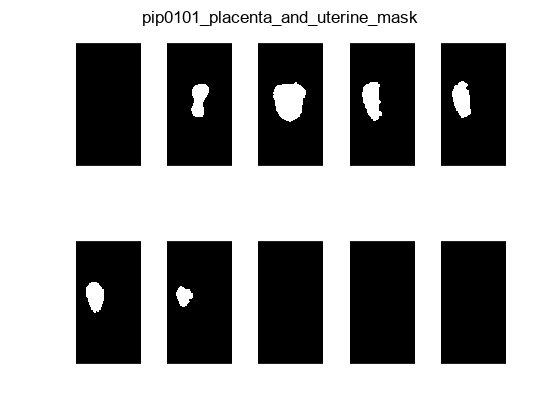

figure
sgtitle('pip0101\_placenta\_and\_uterine\_mask');
j= 1;
for i = 1:3:30
    subplot(2,5,j);
    imshow(pip0101_placenta_and_uterine_mask(:,:,i),[0,1]);
    j = j + 1;
end

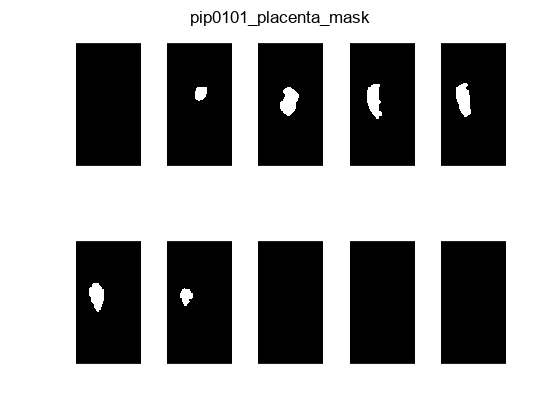

figure
sgtitle('pip0101\_placenta\_mask')
j= 1;
for i = 1:3:30
    subplot(2,5,j);
    imshow(pip0101_placenta_mask(:,:,i),[0,1]);
    j = j + 1;
end

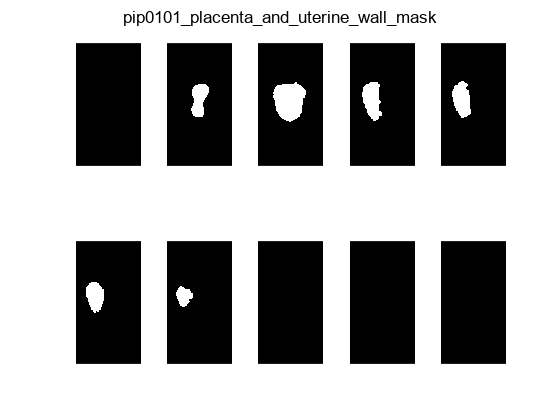

figure
sgtitle('pip0101\_placenta\_and\_uterine\_wall\_mask')
j= 1;
for i = 1:3:30
    subplot(2,5,j);
    imshow(pip0101_placenta_and_uterine_mask(:,:,i),[0,1]);
    j = j + 1;
end

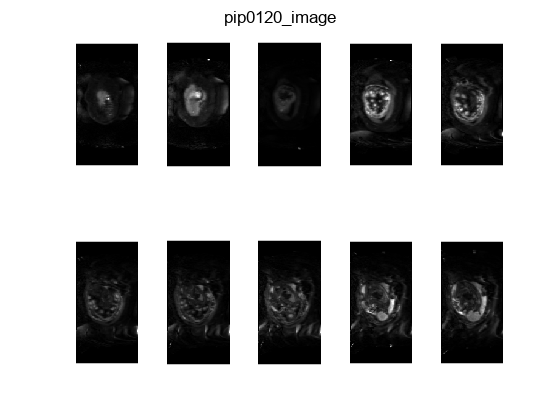

figure
sgtitle('pip0120\_image')
j= 1;
for i = 1:2:20
    subplot(2,5,j);
    img = pip0120_image(:,:,i,1);
    imshow(img,[0,max(img,[],"all")]);
    j = j + 1;
end

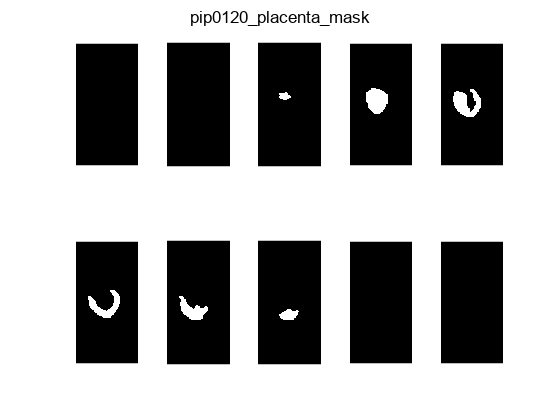

figure
sgtitle('pip0120\_placenta\_mask')
j= 1;
for i = 1:2:20
    subplot(2,5,j);
    imshow(pip0120_placenta_mask(:,:,i),[0,1]);
    j = j + 1;
end

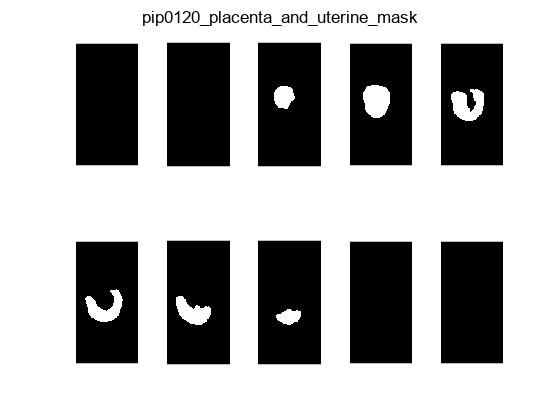

figure
sgtitle('pip0120\_placenta\_and\_uterine\_mask')
j= 1;
for i = 1:2:20
    subplot(2,5,j);
    imshow(pip0120_placenta_and_uterine_mask(:,:,i),[0,1]);
    j = j + 1;
end

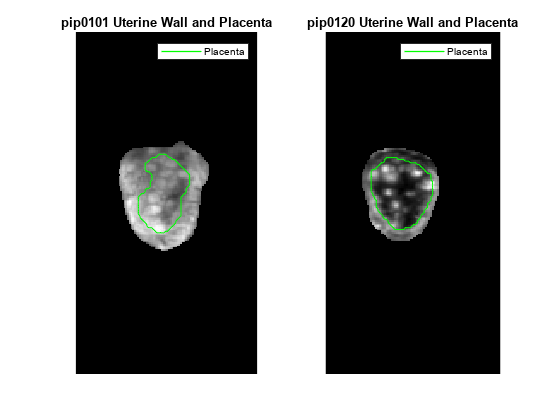

pip0101_placenta_and_uterine_image = pip0101_image(:,:,7,1) .* double(pip0101_placenta_and_uterine_mask(:,:,7));
pip0120_placenta_and_uterine_image = pip0120_image(:,:,7,1) .* double(pip0120_placenta_and_uterine_mask(:,:,7));
figure
subplot(1,2,1);
imshow(pip0101_placenta_and_uterine_image,[0,max(pip0101_placenta_and_uterine_image,[],"all")]);
hold on
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 1)
hold off
legend("Placenta")
title("pip0101 Uterine Wall and Placenta");
subplot(1,2,2)
imshow(pip0120_placenta_and_uterine_image,[0,max(pip0120_placenta_and_uterine_image,[],"all")]);
hold on
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 1)
hold off
legend("Placenta")
title("pip0120 Uterine Wall and Placenta");
saveas(gcf,"CW3\Figures\slice_7_utritne_wall_and_placentas",'epsc');

## Task 2 – Load and plot the MRI acquisition parameters

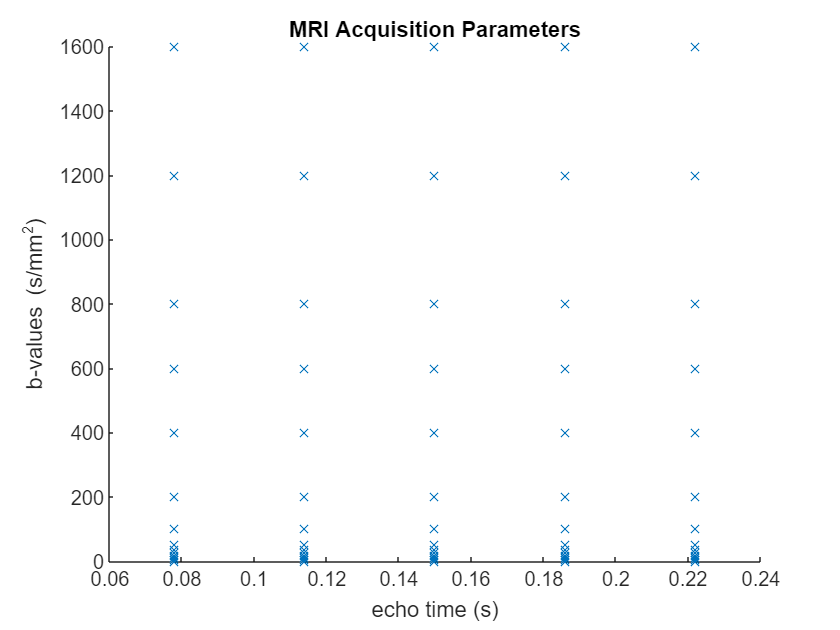

figure("Name","Task2");
grad_echo = readmatrix("CW3\data\grad_echo.txt");
echo_times = grad_echo(:,5);
bvals = grad_echo(:,4);
scatter(echo_times,bvals,"x");
xlabel("echo time (s)");
ylabel("b-values (s/mm^2)");
title("MRI Acquisition Parameters");
saveas(gcf,"CW3\Figures\mri_acquisition_parmeters",'epsc');

## Task 3 – Fit the combined T2*-ADC model

### ROI Parameter **Initialisation **

Avox = squeeze(pip0101_image(100,49,7,:));
x0 = [0,10e-5,0.001]; % 1:S0, 2:d  3:T2_star
lower_bounds = [0,10e-5,0.001];
upper_bounds =[10e5,1,1];

mask = double(pip0101_placenta_and_uterine_mask);
mask(mask==0) = NaN;

ROI_mean = squeeze(mean(pip0101_image .* mask,[1,2,3],'omitnan'));

f = @(x)T2_star_ADC(x,ROI_mean,bvals,echo_times);
options = optimoptions(@fmincon,"Display","iter");

[x0,fval] = fmincon(f,x0,[],[],[],[],lower_bounds,upper_bounds,[],options)

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    1.612897e+05    0.000e+00    1.285e+03
    1      11    1.385890e+05    0.000e+00    2.379e+04    5.211e+01
    2      15    8.418819e+04    0.000e+00    3.259e+06    1.058e+01
    3      22    3.922478e+04    0.000e+00    1.621e+06    1.031e-01
    4      27    3.922301e+04    0.000e+00    3.636e+04    1.773e+00
    5      34    3.902528e+04    0.000e+00    5.790e+05    3.533e+00
    6      39    2.771671e+04    0.000e+00    2.041e+06    2.635e+01
    7      45    2.733067e+04    0.000e+00    8.096e+05    7.473e-01
    8      51    2.598838e+04    0.000e+00    1.422e+06    7.229e+00
    9      56    1.305205e+04    0.000e+00    2.823e+06    1.001e+02
   10      61    1.000875e+04    0.000e+00    5.666e+05    6.858e+00
   11    

x0 =   354.7960    0.0022    0.0443


fval = 2.9615e+03

### Fit to a single voxel

f = @(x)T2_star_ADC(x,Avox,bvals,echo_times);
[x,fval] = fmincon(f,x0,[],[],[],[],lower_bounds,upper_bounds,[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    1.072877e+05    0.000e+00    1.045e+07
    1      14    2.473074e+04    0.000e+00    1.538e+04    1.867e-02
    2      19    2.448627e+04    0.000e+00    3.097e+07    3.257e+01
    3      26    2.345345e+04    0.000e+00    1.710e+07    4.008e+01
    4      31    2.327543e+04    0.000e+00    2.943e+06    9.081e+01
    5      44    2.203918e+04    0.000e+00    6.660e+06    5.601e-03
    6      49    2.201687e+04    0.000e+00    6.348e+06    1.430e-01
    7      53    1.934454e+04    0.000e+00    3.200e+05    1.600e+01
    8      57    1.915586e+04    0.000e+00    1.005e+05    1.396e+01
    9      61    1.910073e+04    0.000e+00    2.553e+05    1.203e+01
   10      65    1.909668e+04    0.000e+00    4.038e+04    9.584e-03
   11      69    1.909657e+04    0.000e+00    1.003e+04    4.814e-01
   12      73    1.909657e+04    0.000e+00    1

x =   330.6033    0.0016    0.0615


fval = 1.9097e+04

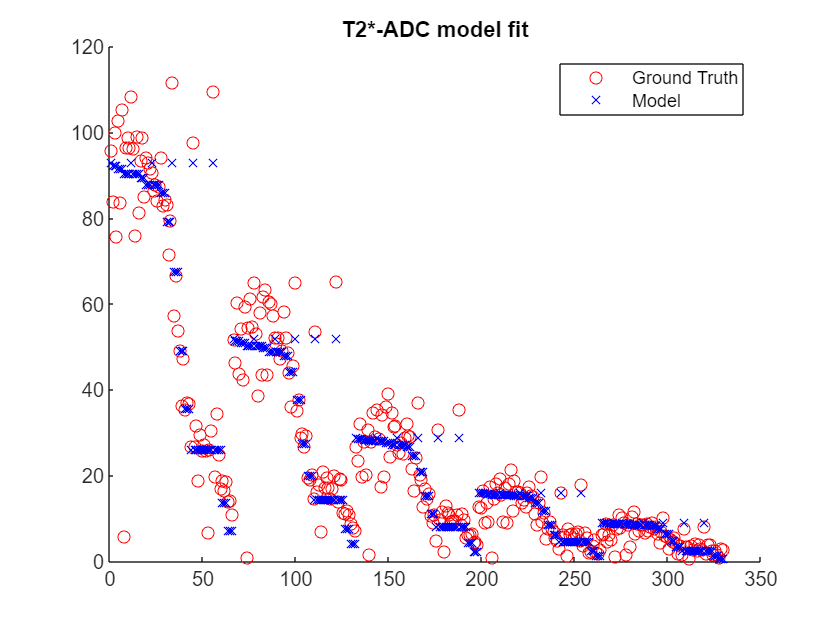

xs = 1:length(Avox);
model = x(1) * exp(-echo_times/x(3)) .* exp(-bvals * x(2));
figure("Name","Single voxel T2_star_ADC fit");
scatter(xs,Avox,"o","CData",[1,0,0])
hold on
scatter(xs,model,"x","CData",[0,0,1]);
title("T2*-ADC model fit");
legend(["Ground Truth","Model"]);
hold off

mask_shape = size(pip0101_placenta_and_uterine_mask(:,:,7));
pip0101_S0_ADC_map = zeros(mask_shape);
pip0101_D_ADC_map = zeros(mask_shape);
pip0101_T_star_ADC_map = zeros(mask_shape);
pip0101_f_values_ADC_map = zeros(mask_shape);
options = optimoptions(@fmincon,"Display","off");

for i = 1:mask_shape(1)
    for j = 1:mask_shape(2)
        if pip0101_placenta_and_uterine_mask(i,j,7) == 1
            Avox = squeeze(pip0101_image(i,j,7,:));
            f = @(x)T2_star_ADC(x,Avox,bvals,echo_times);
            [x,fval] = fmincon(f,x0,[],[],[],[],lower_bounds,upper_bounds,[],options);
            pip0101_S0_ADC_map(i,j) = x(1);
            pip0101_D_ADC_map(i,j) = x(2);
            pip0101_T_star_ADC_map(i,j) = x(3);
            pip0101_f_values_ADC_map(i,j) = fval;
        else
            pip0101_S0_ADC_map(i,j) = NaN;
            pip0101_D_ADC_map(i,j) = NaN;
            pip0101_T_star_ADC_map(i,j) = NaN;
            pip0101_f_values_ADC_map(i,j) = NaN;
        end        
    end
end


### Region of interest paramiter initalization

pip0120_image_slice = pip0120_image(:,:,7,:); 
mask = double(pip0120_placenta_and_uterine_mask);
mask(mask==0) = NaN;

ROI_mean = squeeze(mean(pip0120_image .* mask,[1,2,3],'omitnan'));

f = @(x)T2_star_ADC(x,ROI_mean,bvals,echo_times);
options = optimoptions(@fmincon,"Display","iter");

[x0,fval] = fmincon(f,x0,[],[],[],[],lower_bounds,upper_bounds,[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    3.055513e+04    0.000e+00    5.196e+06
    1       9    2.771387e+04    0.000e+00    3.484e+06    2.155e-02
    2      13    5.346281e+03    0.000e+00    1.137e+06    9.645e+01
    3      18    3.437760e+03    0.000e+00    1.155e+06    9.006e+00
    4      23    2.857011e+03    0.000e+00    1.378e+06    3.757e+00
    5      35    2.101809e+03    0.000e+00    4.097e+06    4.383e-03
    6      40    2.094813e+03    0.000e+00    4.075e+06    1.255e-01
    7      45    1.050067e+03    0.000e+00    8.905e+05    7.401e+01
    8      51    8.321930e+02    0.000e+00    3.933e+05    4.650e+01
    9      56    7.095540e+02    0.000e+00    7.023e+05    9.362e+01
   10      60    5.934410e+02    0.000e+00    5.141e+05    1.319e-01
   11      65    5.551197e+02    0.000e+00    5.764e+04    1.226e+01
   12      69    5.382587e+02    0.000e+00    7

x0 =   444.2937    0.0017    0.0312


fval = 490.6425

mask_shape = size(pip0120_placenta_and_uterine_mask(:,:,7));
pip0120_S0_ADC_map = zeros(mask_shape);
pip0120_D_ADC_map = zeros(mask_shape);
pip0120_T_star_ADC_map = zeros(mask_shape);
pip0120_f_values_ADC_map = zeros(mask_shape);
options = optimoptions(@fmincon,"Display","off");

for i = 1:mask_shape(1)
    for j = 1:mask_shape(2)
        if pip0120_placenta_and_uterine_mask(i,j,7) == 1
            Avox = squeeze(pip0120_image(i,j,7,:));
            f = @(x)T2_star_ADC(x,Avox,bvals,echo_times);
            [x,fval] = fmincon(f,x0,[],[],[],[],lower_bounds,upper_bounds,[],options);
            pip0120_S0_ADC_map(i,j) = x(1);
            pip0120_D_ADC_map(i,j) = x(2);
            pip0120_T_star_ADC_map(i,j) = x(3);
            pip0120_f_values_ADC_map(i,j) = fval;
        else
            pip0120_S0_ADC_map(i,j) = NaN;
            pip0120_D_ADC_map(i,j) = NaN;
            pip0120_T_star_ADC_map(i,j) = NaN;
            pip0120_f_values_ADC_map(i,j) = NaN;
        end        
    end
end

## Task 4 – Compare maps for control and pre-eclampsia participants

### Box plots of parameters  

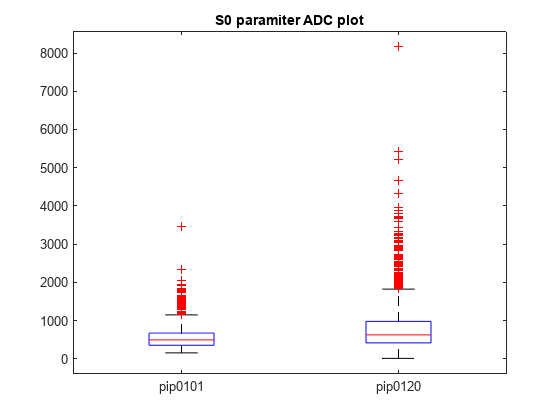

figure
x1 = pip0101_S0_ADC_map(~isnan(pip0101_S0_ADC_map));
x2 = pip0120_S0_ADC_map(~isnan(pip0120_S0_ADC_map));
x = [x1;x2];
g = [zeros(length(x1),1); ones(length(x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("S0 paramiter ADC plot");

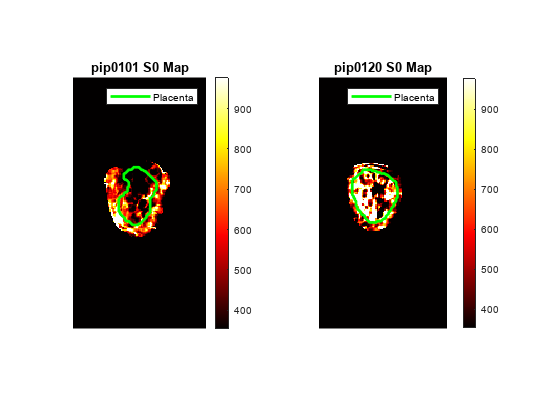

range = [quantile(x1,[.25 .75]) quantile(x2,[.25 .75])];
figure
subplot(1,2,1);
imshow(pip0101_S0_ADC_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0101 S0 Map");
colorbar;
legend("Placenta")
subplot(1,2,2);
imshow(pip0120_S0_ADC_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0120 S0 Map");
legend("Placenta")
colorbar;
saveas(gcf,"CW3\Figures\ADC_S0_maps",'epsc');

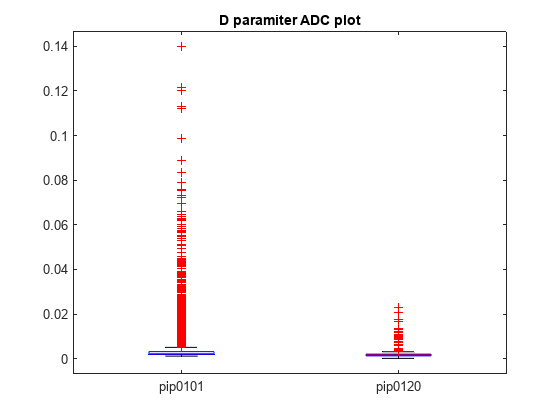

figure
x1 = pip0101_D_ADC_map(~isnan(pip0101_D_ADC_map));
x2 = pip0120_D_ADC_map(~isnan(pip0120_D_ADC_map));
x = [x1;x2];
g = [zeros(length(x1),1); ones(length(x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("D paramiter ADC plot");

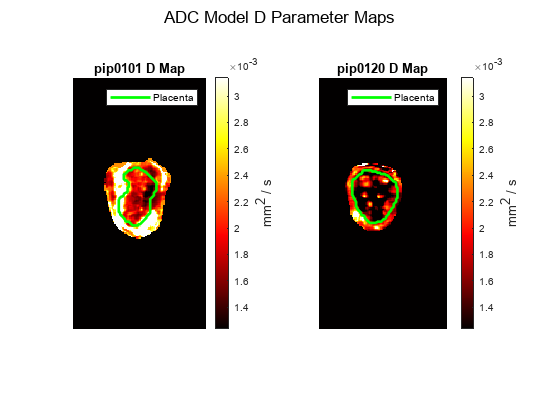

range = [quantile(x1,[.25 .75]) quantile(x2,[.25 .75])];
figure
sgtitle('ADC Model D Parameter Maps')
subplot(1,2,1);
imshow(pip0101_D_ADC_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0101 D Map");
c = colorbar;
c.Label.String = "mm^2 / s";
c.Label.FontSize = 10;
legend("Placenta")
subplot(1,2,2);
imshow(pip0120_D_ADC_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0120 D Map");
c = colorbar;
c.Label.String = "mm^2 / s";
c.Label.FontSize = 10;
legend("Placenta")
saveas(gcf,"CW3\Figures\ADC_D_maps",'epsc');

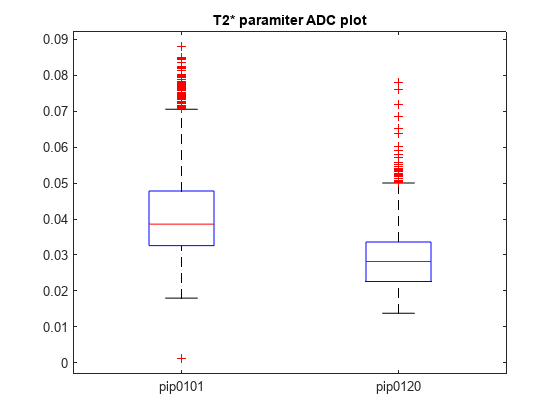

figure
x1 = pip0101_T_star_ADC_map(~isnan(pip0101_T_star_ADC_map));
x2 = pip0120_T_star_ADC_map(~isnan(pip0120_T_star_ADC_map));
x = [x1;x2];
g = [zeros(length(x1),1); ones(length(x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("T2* paramiter ADC plot");

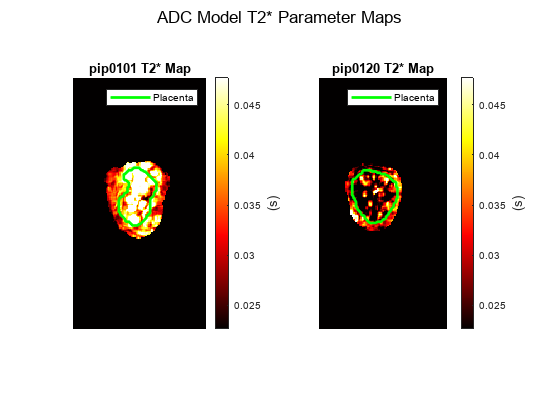

range = [quantile(x1,[.25 .75]) quantile(x2,[.25 .75])];
figure
sgtitle('ADC Model T2* Parameter Maps')
subplot(1,2,1);
imshow(pip0101_T_star_ADC_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0101 T2* Map");
c = colorbar;
c.Label.String = "(s)";
c.Label.FontSize = 10;
legend("Placenta")
subplot(1,2,2);
imshow(pip0120_T_star_ADC_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0120 T2* Map");
c = colorbar;
c.Label.String = "(s)";
c.Label.FontSize = 10;
legend("Placenta")
saveas(gcf,"CW3\Figures\ADC_T2_star_maps",'epsc');

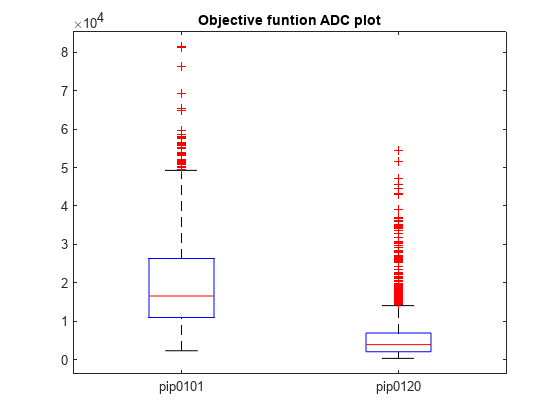

figure
x1 = pip0101_f_values_ADC_map(~isnan(pip0101_f_values_ADC_map));
x2 = pip0120_f_values_ADC_map(~isnan(pip0120_f_values_ADC_map));
x = [x1;x2];
g = [zeros(length(x1),1); ones(length(x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("Objective funtion ADC plot");

## Task 5 – Fit the combined T2*-Intravoxel incoherent motion (IVIM) model

## ROI Parameter **Initialisation**

Avox = squeeze(pip0101_image(100,49,7,:));
x0 = [0,10e-5,0.001,10e-5,0]; % 1:S0, 2:d 3:T2_star 4:Dp 5:f 
lower_bounds = [0,10e-5,0.001,10e-5,0];
upper_bounds =[10e5,1,1,1,1];
A = [0,1,0,-1,0]; % Dp > d therefore d + (-Dp) <= 0
b = 0;

mask = double(pip0101_placenta_and_uterine_mask);
mask(mask==0) = NaN;

ROI_mean = squeeze(mean(pip0101_image .* mask,[1,2,3],'omitnan'));

f = @(x)T2_star_IVIM(x,ROI_mean,bvals,echo_times);
options = optimoptions(@fmincon,"Display","iter");

[x0,fval] = fmincon(f,x0,A,b,[],[],lower_bounds,upper_bounds,[],options)

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.612897e+05    0.000e+00    1.285e+03
    1      15    1.385850e+05    0.000e+00    2.379e+04    5.211e+01
    2      21    1.109762e+05    0.000e+00    2.179e+05    6.840e+00
    3      27    1.087028e+05    0.000e+00    2.446e+05    2.602e-01
    4      34    1.056996e+05    0.000e+00    3.710e+05    1.661e+00
    5      40    5.589265e+04    0.000e+00    2.513e+06    8.702e-01
    6      46    5.498661e+04    0.000e+00    1.836e+07    2.372e-01
    7      52    4.920087e+04    0.000e+00    2.122e+07    1.938e+00
    8      61    4.128807e+04    1.333e-03    2.951e+06    8.067e+00
    9      67    3.956094e+04    2.093e-03    2.816e+06    1.600e+00
   10      73    3.574708e+04    2.077e-03    1.049e+06    2.399e+00
   11    

x0 =   427.8989    0.0018    0.0442    0.0662    0.2999


fval = 800.8557

f = @(x)T2_star_IVIM(x,Avox,bvals,echo_times);
[x,fval] = fmincon(f,x0,A,b,[],[],lower_bounds,upper_bounds,[],options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.072721e+05    0.000e+00    1.039e+07
    1      18    3.160173e+04    0.000e+00    1.151e+05    2.641e-02
    2      27    3.129117e+04    0.000e+00    3.895e+06    4.453e-01
    3      36    2.913842e+04    0.000e+00    8.733e+06    5.317e+01
    4      43    2.496027e+04    0.000e+00    5.416e+06    2.923e+01
    5      50    2.187462e+04    0.000e+00    1.670e+07    5.609e+01
    6      57    2.066253e+04    0.000e+00    6.238e+06    1.048e+01
    7      65    2.060760e+04    0.000e+00    3.814e+06    1.152e+01
    8      73    1.998410e+04    0.000e+00    4.252e+06    5.287e+01
    9      82    1.912439e+04    0.000e+00    5.413e+06    1.963e+01
   10      88    1.851420e+04    0.000e+00    2.961e+05    4.350e+00
   11      97    1.848143e+04    0.000e+00    1.589e+06    1.476e+01
   12     105    1.842231e+04    0.000e+00    1

x =   365.1751    0.0015    0.0615    0.9999    0.1178


fval = 1.8072e+04

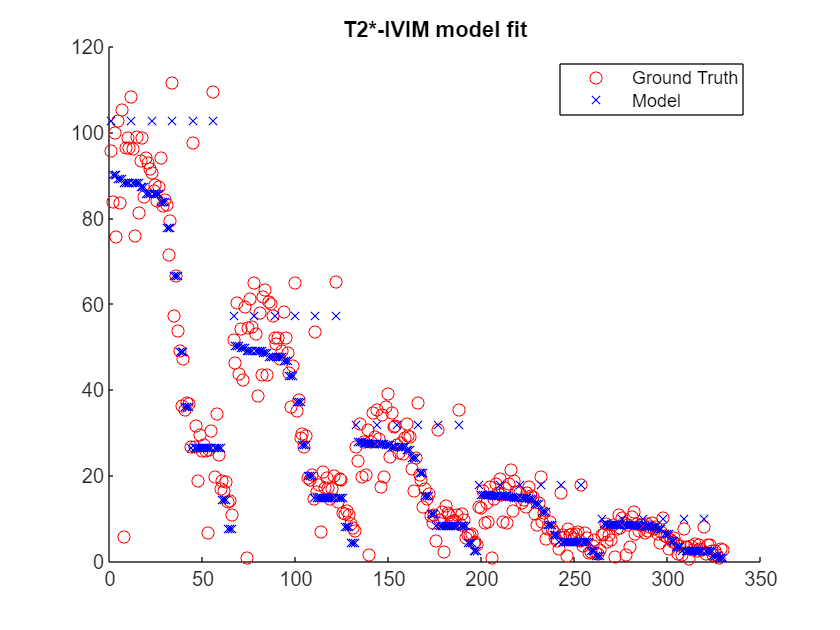

xs = 1:length(Avox);
model = x(1) * exp(-echo_times/x(3)) .* (x(5) * exp(-bvals*x(4)) + (1-x(5)) * exp(-bvals * x(2)));
figure("Name","Single voxel T2_star_IVIM fit");
scatter(xs,Avox,"o","CData",[1,0,0])
hold on
scatter(xs,model,"x","CData",[0,0,1]);
title("T2*-IVIM model fit");
legend(["Ground Truth","Model"]);
hold off

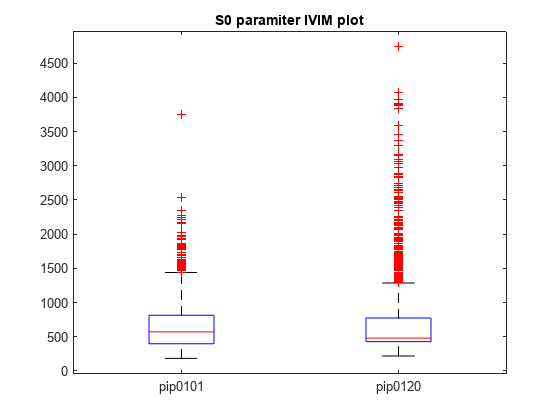


mask_shape = size(pip0101_placenta_and_uterine_mask(:,:,7));
pip0101_S0_IVIM_map = zeros(mask_shape);
pip0101_D_IVIM_map = zeros(mask_shape);
pip0101_T_star_IVIM_map = zeros(mask_shape);
pip0101_Dp_IVIM_map = zeros(mask_shape);
pip0101_f_IVIM_map = zeros(mask_shape);
pip0101_f_values_IVIM_map = zeros(mask_shape);
options = optimoptions(@fmincon,"Display","off");
for i = 1:mask_shape(1)
    for j = 1:mask_shape(2)
        if pip0101_placenta_and_uterine_mask(i,j,7) == 1
            Avox = squeeze(pip0101_image(i,j,7,:));
            f = @(x)T2_star_IVIM(x,Avox,bvals,echo_times);
            [x,fval] = fmincon(f,x0,A,b,[],[],lower_bounds,upper_bounds,[],options);
            pip0101_S0_IVIM_map(i,j) = x(1);
            pip0101_D_IVIM_map(i,j) = x(2);
            pip0101_T_star_IVIM_map(i,j) = x(3);
            pip0101_Dp_IVIM_map(i,j) = x(4);
            pip0101_f_IVIM_map(i,j) = x(5);
            pip0101_f_values_IVIM_map(i,j) = fval;
        else
            pip0101_S0_IVIM_map(i,j) = NaN;
            pip0101_D_IVIM_map(i,j) = NaN;
            pip0101_T_star_IVIM_map(i,j) = NaN;
            pip0101_Dp_IVIM_map(i,j) = NaN;
            pip0101_f_IVIM_map(i,j) = NaN;
            pip0101_f_values_IVIM_map(i,j) = NaN;

        end        
    end
end
mask_shape = size(pip0120_placenta_and_uterine_mask(:,:,7));
pip0120_S0_IVIM_map = zeros(mask_shape);
pip0120_D_IVIM_map = zeros(mask_shape);
pip0120_T_star_IVIM_map = zeros(mask_shape);
pip0120_Dp_IVIM_map = zeros(mask_shape);
pip0120_f_IVIM_map = zeros(mask_shape);
pip0120_f_values_IVIM_map = zeros(mask_shape);
for i = 1:mask_shape(1)
    for j = 1:mask_shape(2)
        if pip0120_placenta_and_uterine_mask(i,j,7) == 1
            Avox = squeeze(pip0120_image(i,j,7,:));
            f = @(x)T2_star_IVIM(x,Avox,bvals,echo_times);
            [x,fval] = fmincon(f,x0,A,b,[],[],lower_bounds,upper_bounds,[],options);
            pip0120_S0_IVIM_map(i,j) = x(1);
            pip0120_D_IVIM_map(i,j) = x(2);
            pip0120_T_star_IVIM_map(i,j) = x(3);
            pip0120_Dp_IVIM_map(i,j) = x(4);
            pip0120_f_IVIM_map(i,j) = x(5);
            pip0120_f_values_IVIM_map(i,j) = fval;
        else
            pip0120_S0_IVIM_map(i,j) = NaN;
            pip0120_D_IVIM_map(i,j) = NaN;
            pip0120_T_star_IVIM_map(i,j) = NaN;
            pip0120_Dp_IVIM_map(i,j) = NaN;
            pip0120_f_IVIM_map(i,j) = NaN;
            pip0120_f_values_IVIM_map(i,j) = NaN;

        end        
    end
end
figure
x1 = pip0101_S0_IVIM_map(~isnan(pip0101_S0_IVIM_map));
x2 = pip0120_S0_IVIM_map(~isnan(pip0120_S0_IVIM_map));
x = [x1;x2];
g = [zeros(length(x1),1); ones(length(x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("S0 paramiter IVIM plot");

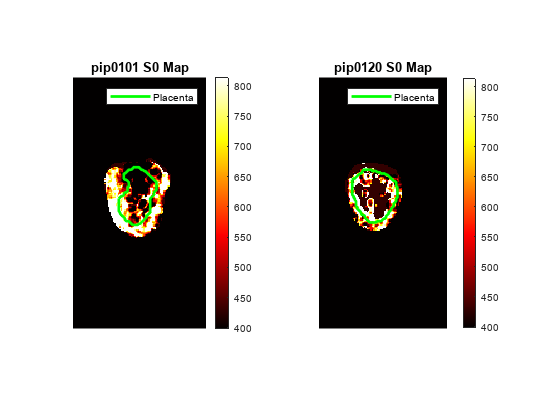

range = [quantile(x1,[.25 .75]) quantile(x2,[.25 .75])];
figure
subplot(1,2,1);
imshow(pip0101_S0_IVIM_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0101 S0 Map");
colorbar;
legend("Placenta")
subplot(1,2,2);
imshow(pip0120_S0_IVIM_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0120 S0 Map");
colorbar;
legend("Placenta")
saveas(gcf,"CW3\Figures\IVIM_S0_maps",'epsc');

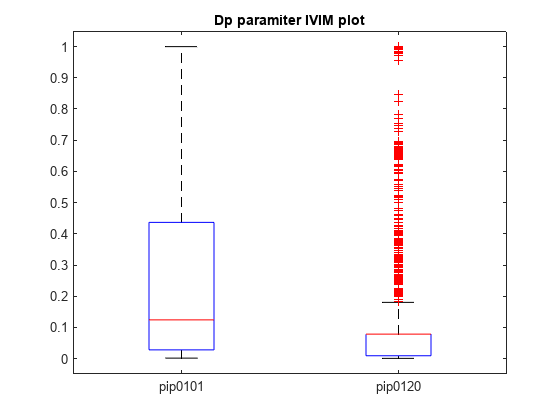

figure
dp_x1 = pip0101_Dp_IVIM_map(~isnan(pip0101_Dp_IVIM_map));
dp_x2 = pip0120_Dp_IVIM_map(~isnan(pip0120_Dp_IVIM_map));
x = [dp_x1;dp_x2];
g = [zeros(length(dp_x1),1); ones(length(dp_x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("Dp paramiter IVIM plot");

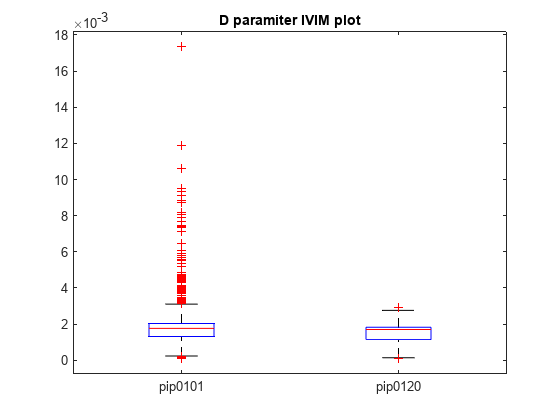

figure
d_x1 = pip0101_D_IVIM_map(~isnan(pip0101_D_IVIM_map));
d_x2 = pip0120_D_IVIM_map(~isnan(pip0120_D_IVIM_map));
x = [d_x1;d_x2];
g = [zeros(length(d_x1),1); ones(length(d_x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("D paramiter IVIM plot");

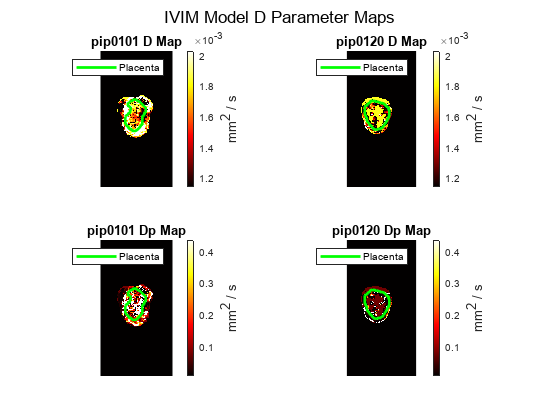

d_range = [quantile(d_x1,[.25 .75]) quantile(d_x2,[.25 .75])];
dp_range = [quantile(dp_x1,[.25 .75]) quantile(dp_x2,[.25 .75])];
figure
sgtitle('IVIM Model D Parameter Maps')
subplot(2,2,1);
imshow(pip0101_D_IVIM_map,[min(d_range),max(d_range)],colormap=hot);
hold on;
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0101 D Map");
c = colorbar;
c.Label.String = "mm^2 / s";
c.Label.FontSize = 10;
legend("Placenta")
subplot(2,2,2);
imshow(pip0120_D_IVIM_map,[min(d_range),max(d_range)],colormap=hot);
hold on;
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0120 D Map");
c = colorbar;
c.Label.String = "mm^2 / s";
c.Label.FontSize = 10;
legend("Placenta")
subplot(2,2,3);
imshow(pip0101_Dp_IVIM_map,[min(dp_range),max(dp_range)],colormap=hot);
hold on;
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0101 Dp Map");
c = colorbar;
c.Label.String = "mm^2 / s";
c.Label.FontSize = 10;
legend("Placenta")
subplot(2,2,4);
imshow(pip0120_Dp_IVIM_map,[min(dp_range),max(dp_range)],colormap=hot);
hold on;
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0120 Dp Map");
c = colorbar;
c.Label.String = "mm^2 / s";
c.Label.FontSize = 10;
legend("Placenta")
saveas(gcf,"CW3\Figures\IVIM_D_and_Dp_maps",'epsc');

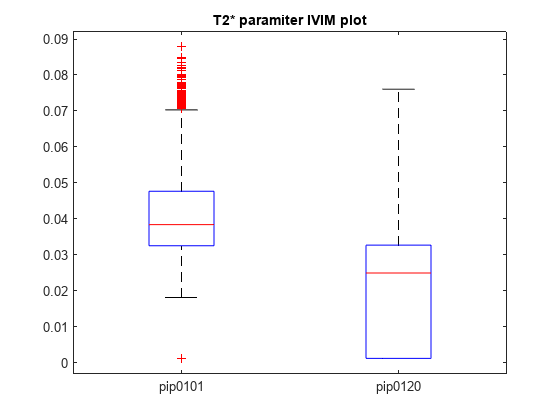

figure
x1 = pip0101_T_star_IVIM_map(~isnan(pip0101_T_star_IVIM_map));
x2 = pip0120_T_star_IVIM_map(~isnan(pip0120_T_star_IVIM_map));
x = [x1;x2];
g = [zeros(length(x1),1); ones(length(x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("T2* paramiter IVIM plot");

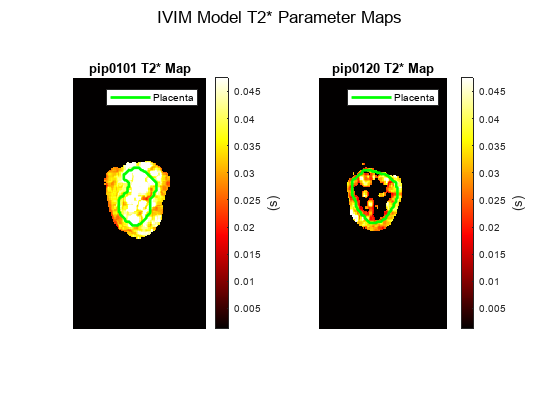

range = [quantile(x1,[.25 .75]) quantile(x2,[.25 .75])];
figure
sgtitle('IVIM Model T2* Parameter Maps')
subplot(1,2,1);
imshow(pip0101_T_star_IVIM_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0101 T2* Map");
c = colorbar;
c.Label.String = "(s)";
c.Label.FontSize = 10;
legend("Placenta")
subplot(1,2,2);
imshow(pip0120_T_star_IVIM_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0120 T2* Map");
c = colorbar;
c.Label.String = "(s)";
c.Label.FontSize = 10;
legend("Placenta")
saveas(gcf,"CW3\Figures\IVIM_T2_star_maps",'epsc');

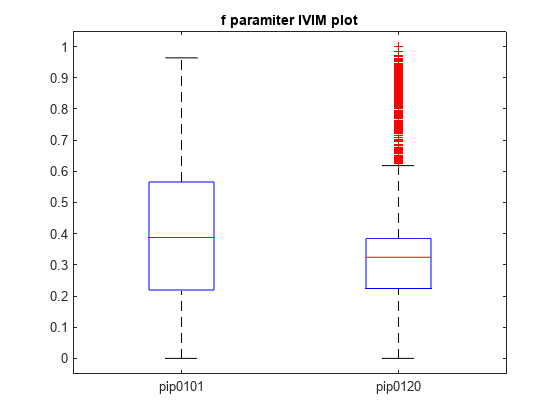

figure
x1 = pip0101_f_IVIM_map(~isnan(pip0101_f_IVIM_map));
x2 = pip0120_f_IVIM_map(~isnan(pip0120_f_IVIM_map));
x = [x1;x2];
g = [zeros(length(x1),1); ones(length(x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("f paramiter IVIM plot");

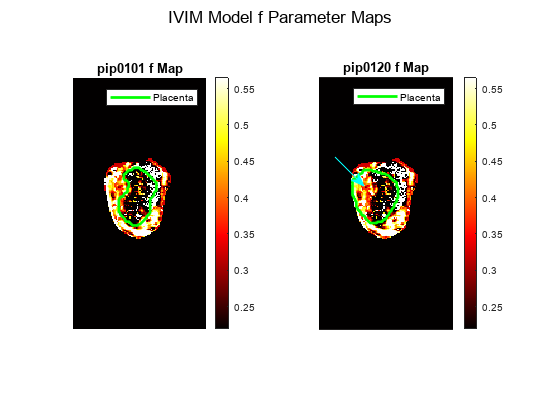

range = [quantile(x1,[.25 .75]) quantile(x2,[.25 .75])];
figure
sgtitle('IVIM Model f Parameter Maps')
subplot(1,2,1);
imshow(pip0101_f_IVIM_map,[min(range),max(range)],colormap=hot);
hold on;
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0101 f Map");
colorbar;
legend("Placenta")
subplot(1,2,2);
imshow(pip0101_f_IVIM_map,[min(range),max(range)],colormap=hot);
ar = annotation("arrow", [0.5982 0.65], [0.6262 0.5571]);
ar.Color = [0,1,1];
hold on;
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0120 f Map");
colorbar;
legend("Placenta")
saveas(gcf,"CW3\Figures\IVIM_f_maps",'epsc');

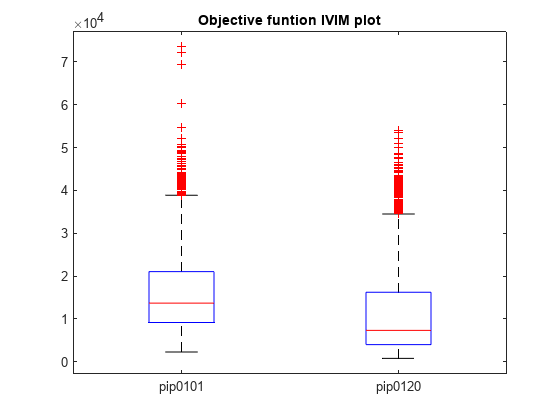

figure
x1 = pip0101_f_values_IVIM_map(~isnan(pip0101_f_values_IVIM_map));
x2 = pip0120_f_values_IVIM_map(~isnan(pip0120_f_values_IVIM_map));
x = [x1;x2];
g = [zeros(length(x1),1); ones(length(x2),1)];
boxplot(x,g,'Labels',["pip0101","pip0120"])
title("Objective funtion IVIM plot");

## Task 6 – Model selection with BIC

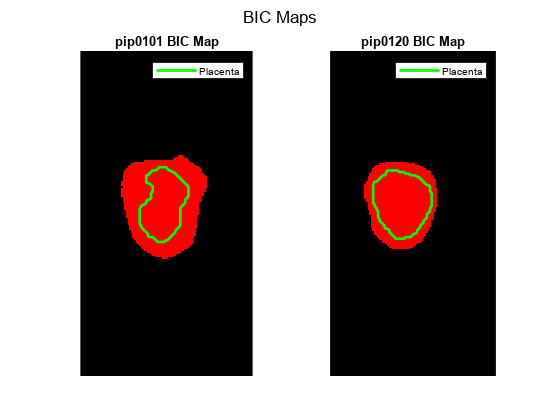

n = 330;
ADC_paramiter_number = 3;
IVIM_paramiter_number = 5;
pip0101_ADC_BIC_MAP = zeros(size(pip0101_f_values_ADC_map));
pip0101_IVIM_BIC_MAP = zeros(size(pip0101_f_values_IVIM_map));
pip0120_ADC_BIC_MAP = zeros(size(pip0120_f_values_ADC_map));
pip0120_IVIM_BIC_MAP = zeros(size(pip0120_f_values_IVIM_map));

pip0101_BIC_MAP = zeros(200,106,3);
pip0120_BIC_MAP = zeros(200,102, 3);

for i = 1:pip0101_size(1)
    for j = 1:pip0101_size(2)
        ADC_L = pip0101_f_values_ADC_map(i,j);
        IVIM_L = pip0101_f_values_IVIM_map(i,j);
        if ~isnan(ADC_L) && ~isnan(IVIM_L)
            ADC_BIC = BIC(ADC_paramiter_number,n,ADC_L); 
            IVIM_BIC = BIC(IVIM_paramiter_number,n,IVIM_L); 
            if ADC_BIC < IVIM_BIC
                pip0101_BIC_MAP(i,j,:) = [1,0,0];
            else
                pip0101_BIC_MAP(i,j,:) = [0,0,1];
            end
        end
    end
end

for i = 1:pip0120_size(1)
    for j = 1:pip0120_size(2)
        ADC_L = pip0120_f_values_ADC_map(i,j);
        IVIM_L = pip0120_f_values_IVIM_map(i,j);
        if ~isnan(ADC_L) && ~isnan(IVIM_L)
            ADC_BIC = BIC(ADC_paramiter_number,n,ADC_L); 
            IVIM_BIC = BIC(IVIM_paramiter_number,n,IVIM_L); 
            if ADC_BIC < IVIM_BIC
                pip0120_BIC_MAP(i,j,:) = [1,0,0];
            else
                pip0120_BIC_MAP(i,j,:) = [0,0,1];
            end
        end
    end
end
figure
sgtitle('BIC Maps')
subplot(1,2,1);
imshow(pip0101_BIC_MAP);
hold on;
plot(B1{1}(:,2), B1{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0101 BIC Map");
legend("Placenta")
subplot(1,2,2);
imshow(pip0120_BIC_MAP);
hold on;
plot(B2{1}(:,2), B2{1}(:,1), 'g', 'LineWidth', 2);
hold off;
title("pip0120 BIC Map");
legend("Placenta")
saveas(gcf,"CW3\Figures\BIC_maps",'epsc');

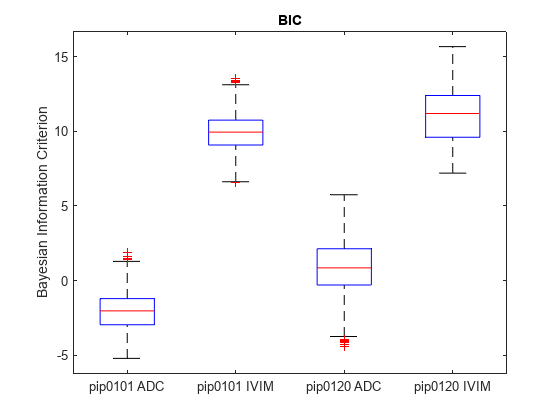

for i = 1:pip0101_size(1)
    for j = 1:pip0101_size(2)
        L = pip0101_f_values_ADC_map(i,j);
        if  ~isnan(L)
            pip0101_ADC_BIC_MAP(i,j) = BIC(ADC_paramiter_number,n,L);
        else
            pip0101_ADC_BIC_MAP(i,j) = NaN;
        end
        L = pip0101_f_values_IVIM_map(i,j);
        if ~isnan(L)
            pip0101_IVIM_BIC_MAP(i,j) = BIC(IVIM_paramiter_number,n,L);
        else
            pip0101_IVIM_BIC_MAP(i,j) = NaN;
        end
    end
end

for i = 1:pip0120_size(1)
    for j = 1:pip0120_size(2)
        L = pip0120_f_values_ADC_map(i,j);
        if  ~isnan(L)
            pip0120_ADC_BIC_MAP(i,j) = BIC(ADC_paramiter_number,n,L);
        else
            pip0120_ADC_BIC_MAP(i,j) = NaN;
        end
        L = pip0120_f_values_IVIM_map(i,j);
        if ~isnan(L)
            pip0120_IVIM_BIC_MAP(i,j) = BIC(IVIM_paramiter_number,n,L);
        else
            pip0120_IVIM_BIC_MAP(i,j) = NaN;
        end
    end
end

figure
x1 = pip0101_ADC_BIC_MAP(~isnan(pip0101_ADC_BIC_MAP));
x2 = pip0101_IVIM_BIC_MAP(~isnan(pip0101_IVIM_BIC_MAP));
x3 = pip0120_ADC_BIC_MAP(~isnan(pip0120_ADC_BIC_MAP));
x4 = pip0120_IVIM_BIC_MAP(~isnan(pip0120_IVIM_BIC_MAP));
x = [x1;x2;x3;x4];
g = [zeros(length(x1),1); ones(length(x2),1); 2* ones(length(x3),1); 3 * ones(length(x4),1)];
boxplot(x,g,'Labels',["pip0101 ADC","pip0101 IVIM","pip0120 ADC","pip0120 IVIM"])
ylabel("Bayesian Information Criterion")
title("BIC");
saveas(gcf,"CW3\Figures\BIC_box_plots",'epsc');

## Task 7 – Continuum modelling

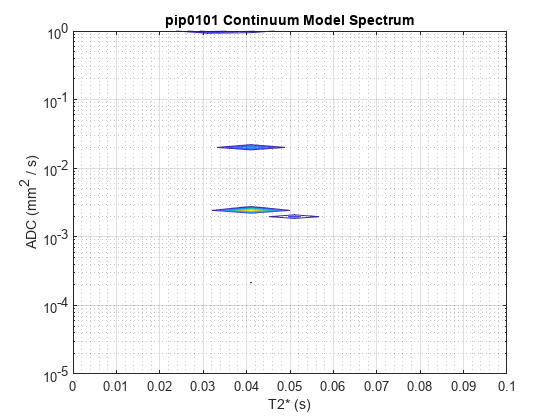

slice1 = squeeze(pip0101_image(:,:,7,:));
slice2 = squeeze(pip0120_image(:,:,7,:));
t2 = 0.001:0.01:1.1;
N_t2 = length(t2);
d = logspace(-5,0,110);
N_d = length(d);
K = zeros(330,N_d * N_t2);
k = 1;

for i = 1:N_t2
    for j = 1:N_d
        K(:,k) = exp(-echo_times/t2(i)) .* exp(-bvals * d(j));
        k = k + 1;
    end
end

mask1 = double(pip0101_placenta_and_uterine_mask);
mask1(mask1==0) = NaN;

mask2 = double(pip0120_placenta_and_uterine_mask);
mask2(mask1==0) = NaN;


S1 = squeeze(mean(pip0101_image .* double(mask1),[1,2,3],'omitnan')); %Length Ns
S2 = squeeze(mean(pip0120_image .* double(mask2),[1,2,3],'omitnan')); %Length Ns


F1 = lsqnonneg(K,S1);
F1 = reshape(F1,N_d,N_t2);
F2 = lsqnonneg(K,S2);
F2 = reshape(F2,N_d,N_t2);

figure
contour(t2,d,F1)
title("pip0101 Continuum Model Spectrum")
set(gca,'Yscale','log')
xlim([0 0.1])
ylabel("ADC (mm^2 / s)")
xlabel("T2* (s)")
grid on
grid minor
saveas(gcf,"CW3\Figures\pip0101_continuum_spectrum",'epsc');

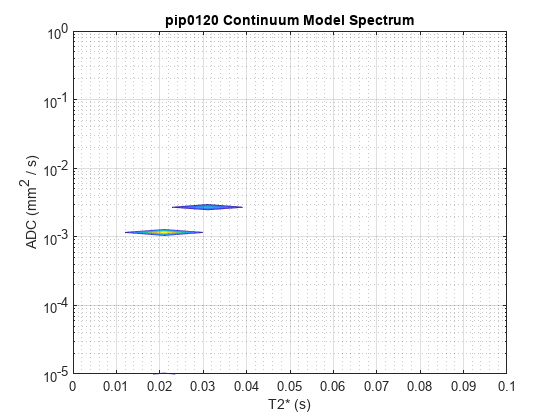

figure 
contour(t2,d,F2)
title("pip0120 Continuum Model Spectrum")
set(gca,'Yscale','log')
xlim([0 0.1])
ylabel("ADC (mm^2 / s)")
xlabel("T2* (s)")
grid on
grid minor
saveas(gcf,"CW3\Figures\pip0120_continuum_spectrum",'epsc');